# 离散时间系统单位脉冲响应

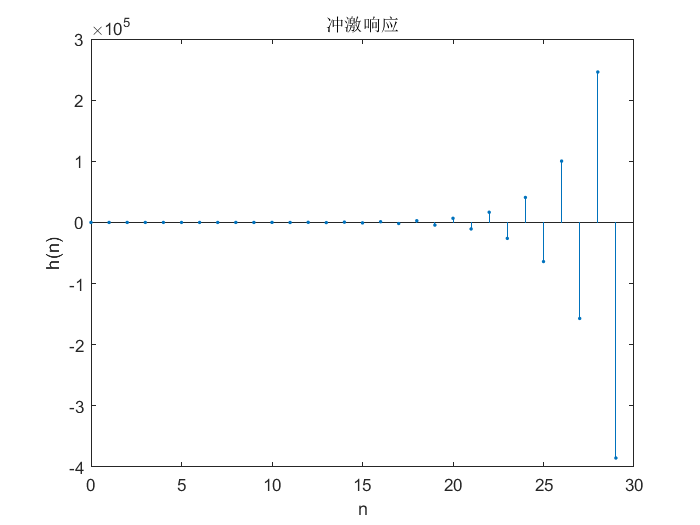

clc
clear
close all;
a=[5,4,-6];
b=[2,-5,3];

% %x为冲激函数
% [x,n]=impseq(0,-20,120);
% %对传递函数滤波
% h=filter(b,a,x);

%数字滤波器脉冲响应
[h,n] = impz(b,a);

figure(1)
%绘制离散序列数据
stem(n,h,'.');
title('冲激响应');
xlabel('n');
ylabel('h(n)');

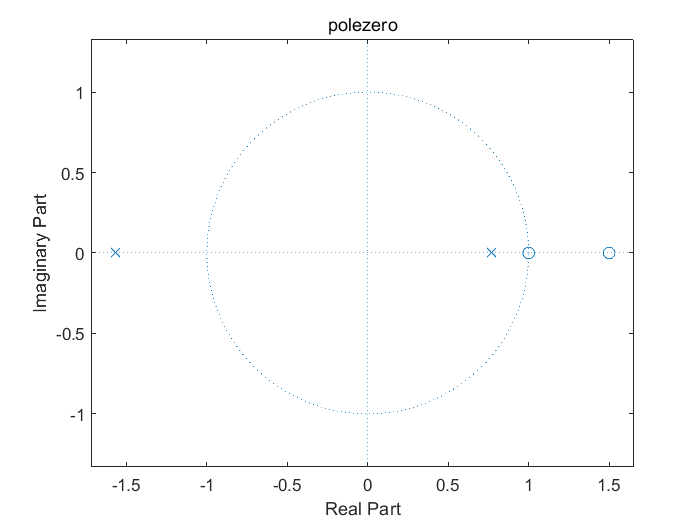


[z,p,g]=tf2zp(b,a);
zplane(z,p)
title('polezero');

% fvtool(b,a,'polezero')
% [b,a] = eqtflength(b,a);
% [z,p,k] = tf2zp(b,a)

function [x,n]=impseq(n0,n1,n2)
n=(n1:n2);
x=((n-n0)==0);
end